# Dribble Analysis

This is the initial experimentaiton done on the dribbling data.

## Dribbling

We're going to start off looking at standard dribbling

dribble = load("dribble.mat");

Let's take a look at the acceleration data (sampled at 10 Hz).

d_a = dribble.Acceleration

d_a = 920×3 timetable
           Timestamp               X          Y         Z   
    ________________________    _______    _______    ______

    22-Nov-2019 19:37:56.819    -2.5581    -5.0934    8.9994
    22-Nov-2019 19:37:56.837    -2.0098    -5.1988    8.4907
    22-Nov-2019 19:37:56.855    -1.6579    -5.9254    7.7724
    22-Nov-2019 19:37:56.873    -1.7848      -5.51    7.2817
    22-Nov-2019 19:37:56.891    -1.5705    -5.3388    7.4361
    22-Nov-2019 19:37:56.909    -1.6771    -5.0108    7.5929
    22-Nov-2019 19:37:56.927    -1.9416    -4.8121    7.7808
    22-Nov-2019 19:37:56.945    -2.1918    -4.7942    7.8981
    22-Nov-2019 19:37:56.963    -2.2804     -4.793    8.0909
    22-No

Convert Timestamp into seconds and crop out unnecessary data

d_t = posixtime(d_a.Timestamp);
d_t = d_t(100:410);
d_t = d_t - d_t(1)

d_t =          0
    0.0180
    0.0360
    0.0540
    0.0720
    0.0900
    0.1080
    0.1260
    0.1440
    0.1620



d_az = d_a.Z(100:410);

Plot z component acceleartion against time in seconds

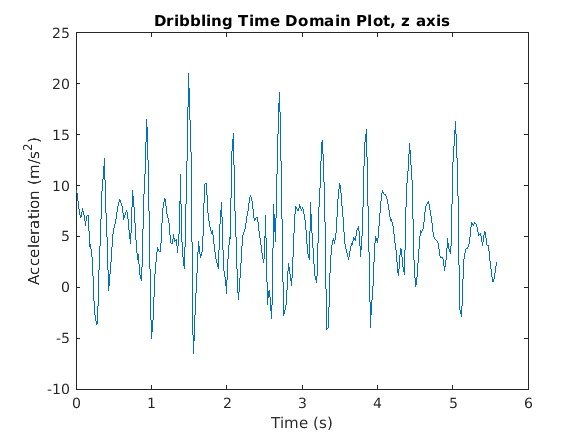

figure;
plot(d_t, d_az);
title("Dribbling Time Domain Plot, z axis");
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");

Take the DFT of x component accelration signal

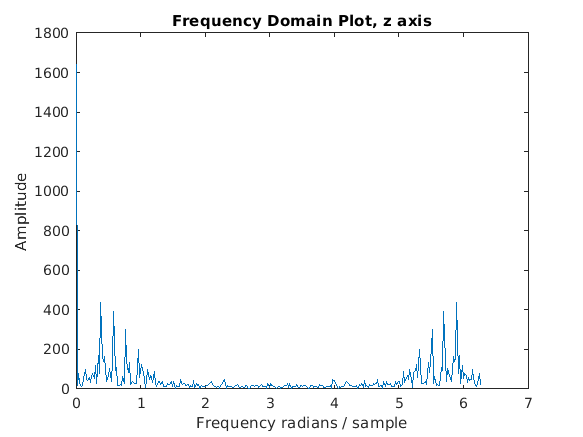

N = length(d_az);
dftz = fft(d_az);
freqs = linspace(0, 2*pi*(N-1)/N, N);

figure;
plot(freqs, abs(dftz))
title("Frequency Domain Plot, z axis");
xlabel('Frequency radians / sample');
ylabel('Amplitude');

Center frequency plot around 0

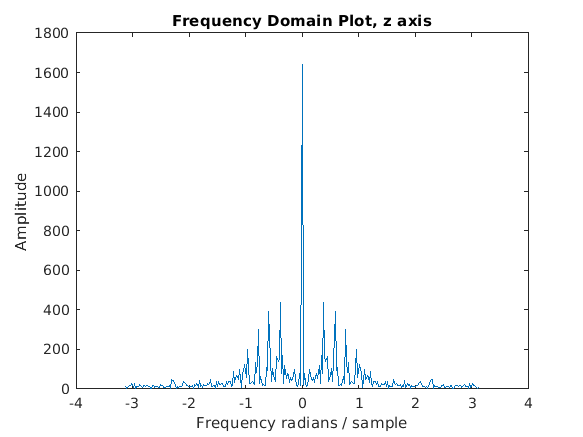

figure;
Z_shifted = fftshift(dftz);
freqs_shifted_radians_per_sample = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(freqs_shifted_radians_per_sample, abs(Z_shifted));
title("Frequency Domain Plot, z axis");
xlabel('Frequency radians / sample');
ylabel('Amplitude');

Convert to more interpretable results with frequency in Hz

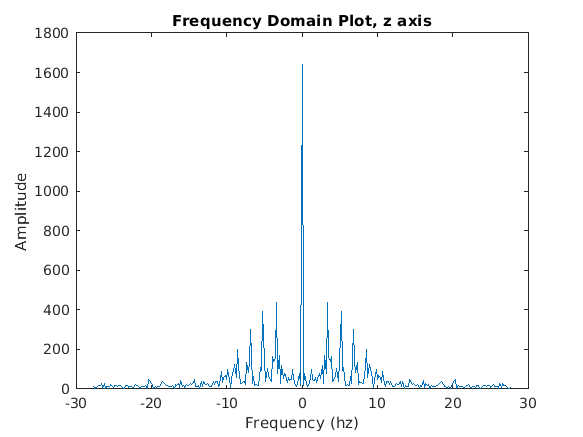

figure;
Fs = 1/(d_t(2)-d_t(1));
freqs_shifted_hz = freqs_shifted_radians_per_sample*Fs/(2*pi);
plot(freqs_shifted_hz, abs(Z_shifted));
title("Frequency Domain Plot, z axis");
xlabel('Frequency (hz)');
ylabel('Amplitude');

Apply DT 7 Point Moving Average Filter

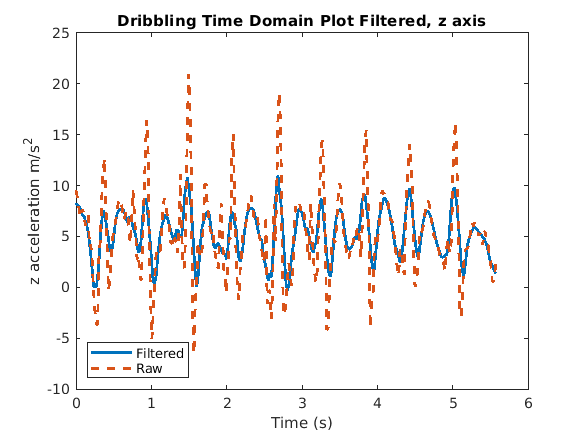

d_azFiltered = movmean(d_az, 7);

fig = figure;
h = plot(d_t, d_azFiltered);
set(h,'LineWidth', 2);
hold on;
h = plot(d_t, d_az, '--');
set(h,'LineWidth', 2);

lgd = legend({'Filtered', 'Raw'});
set(lgd, 'Location', 'SouthWest');

xlabel('Time (s)');
ylabel('z acceleration m/s^2');
title('Dribbling Time Domain Plot Filtered, z axis')

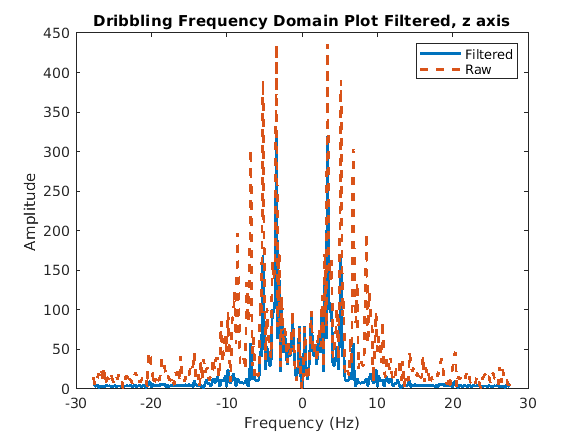


fig = figure;
N = length(d_azFiltered);
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

% Remove 0 frequency (artifact of FFT)
h = plot(f, abs(fftshift(fft(d_azFiltered - mean(d_azFiltered)))));
set(h,'LineWidth', 2);

hold on;
h = plot(f, abs(fftshift(fft(d_az - mean(d_az)))), '--');
set(h,'LineWidth', 2);

lgd = legend({'Filtered', 'Raw'});

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Dribbling Frequency Domain Plot Filtered, z axis')

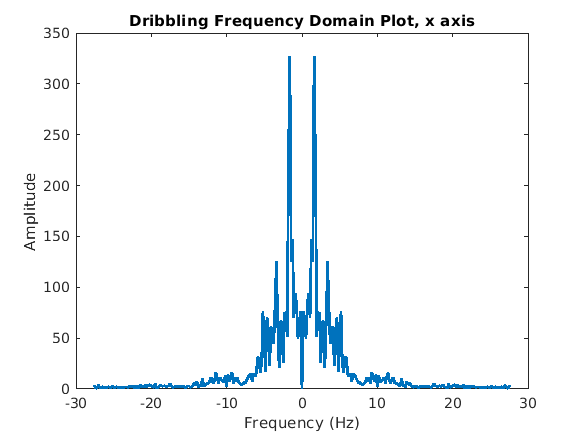

d_az = d_a.X(100:410);

d_azFiltered = movmean(d_az, 7);

fig = figure;
N = length(d_azFiltered);
Fs = 1/(d_t(2)-d_t(1));
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

% Remove 0 frequency (artifact of FFT)
h = plot(f, abs(fftshift(fft(d_azFiltered - mean(d_azFiltered)))));
set(h,'LineWidth', 2);

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Dribbling Frequency Domain Plot, x axis')

## Cross Over

cross = load("cross_over.mat");

d_a_cross = cross.Acceleration;
d_t_cross = posixtime(d_a_cross.Timestamp);
d_t_cross = d_t_cross(60:800);
d_t_cross = d_t_cross - d_t_cross(1);
d_az_cross = d_a_cross.Z(60:800);

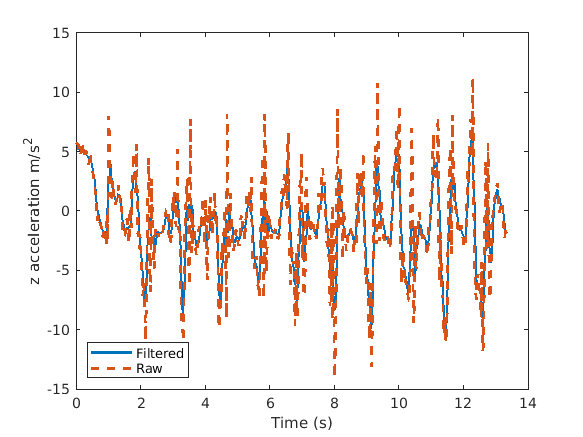

d_azFiltered = movmean(d_az_cross, 7);

fig = figure;
h = plot(d_t_cross, d_azFiltered);
set(h,'LineWidth', 2);
hold on;
h = plot(d_t_cross, d_az_cross, '--');
set(h,'LineWidth', 2);

lgd = legend({'Filtered', 'Raw'});
set(lgd, 'Location', 'SouthWest');

xlabel('Time (s)');
ylabel('z acceleration m/s^2');

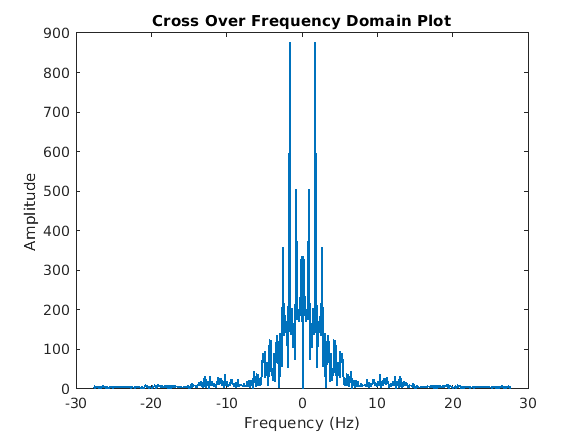


fig = figure;
N = length(d_azFiltered);
Fs = 1/(d_t_cross(2)-d_t_cross(1));
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

% Remove 0 frequency (artifact of FFT)
h = plot(f, abs(fftshift(fft(d_azFiltered - mean(d_azFiltered)))));
set(h,'LineWidth', 2);

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Cross Over Frequency Domain Plot')

## In&Out

inout = load("in_out.mat");

d_a_inout = inout.Acceleration;
d_t_inout = posixtime(d_a_inout.Timestamp);
d_t_inout = d_t_inout(60:450);
d_t_inout = d_t_inout - d_t_inout(1);
d_az_inout = d_a_inout.Z(60:450);

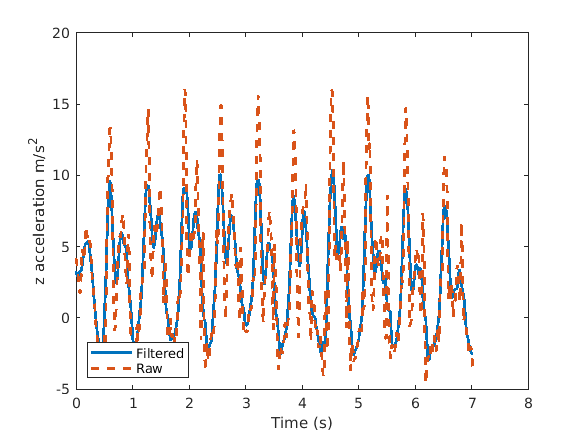

d_azFiltered = movmean(d_az_inout, 7);

fig = figure;
h = plot(d_t_inout, d_azFiltered);
set(h,'LineWidth', 2);
hold on;
h = plot(d_t_inout, d_az_inout, '--');
set(h,'LineWidth', 2);

lgd = legend({'Filtered', 'Raw'});
set(lgd, 'Location', 'SouthWest');

xlabel('Time (s)');
ylabel('z acceleration m/s^2');

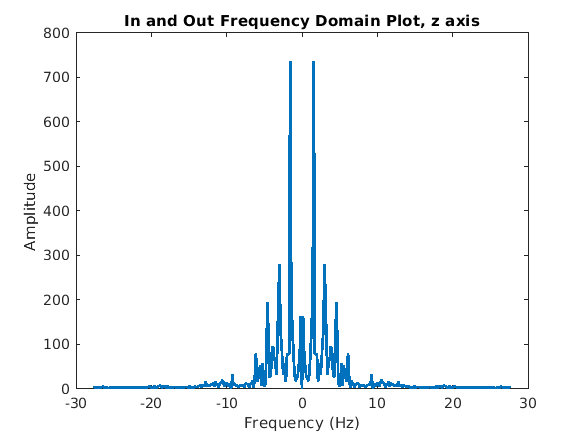


fig = figure;
N = length(d_azFiltered);
Fs = 1/(d_t_inout(2)-d_t_inout(1));
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

% Remove 0 frequency (artifact of FFT)
h = plot(f, abs(fftshift(fft(d_azFiltered - mean(d_azFiltered)))));
set(h,'LineWidth', 2);

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('In and Out Frequency Domain Plot, z axis')

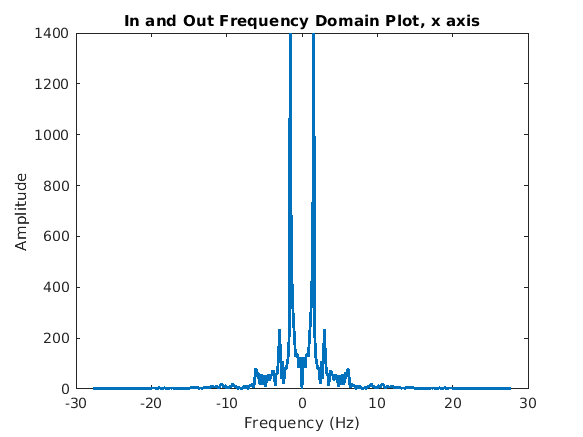

d_az_inout = d_a_inout.X(60:450);

d_azFiltered = movmean(d_az_inout, 7);

fig = figure;
N = length(d_azFiltered);
Fs = 1/(d_t_inout(2)-d_t_inout(1));
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

% Remove 0 frequency (artifact of FFT)
h = plot(f, abs(fftshift(fft(d_azFiltered - mean(d_azFiltered)))));
set(h,'LineWidth', 2);

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('In and Out Frequency Domain Plot, x axis')